**21AIE303 - Signal and Image Processing**

**Evaluation 1 – Assignment-1- 2D convolution**

Submitted by Vishnu Radhakrishnan

CB.EN.U4AIE20074

clc
clear all
close all

- Write your own function in matlab/python to compute the following.

Stride is the number of pixels shifts over the input matrix.

Padding is a process of adding layers of zeros to our input images.

(i) Convolution with input containing single depth.

%Example given in class
A=[22,15,1,3,60;
    42,5,38,39,7;
    28,9,4,66,79;
    0,82,45,12,17;
    99,14,72,51,3];
%0 padding and stride 1
B=[0,0,1;0,0,0;0,0,0];
output= Convo2D(A,B,0,1)

output =      1     3    60
    38    39     7
     4    66    79


img=imread("Lena512.png");%Taken Lena Image for single depth / grayscale
img=im2double(img);
filter = [-1,-2,-1;0,0,0;1,2,1]; %Edge detection filter
filter1 = [1,2,1;0,0,0;-1,-2,-1]

filter1 =      1     2     1
     0     0     0
    -1    -2    -1


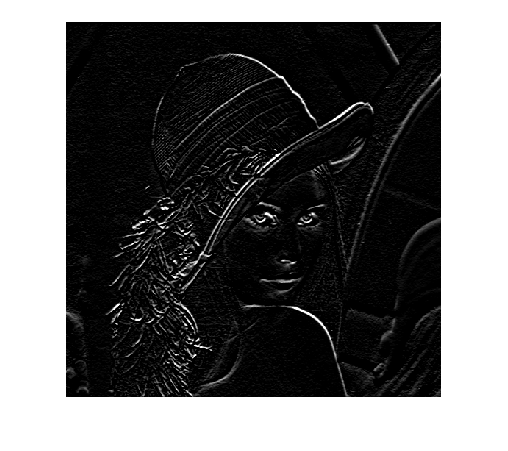

%Giving 2 padding and stride 1 to get full convolution 
final = Convo2D(img,filter,0,1);
imshow(final)

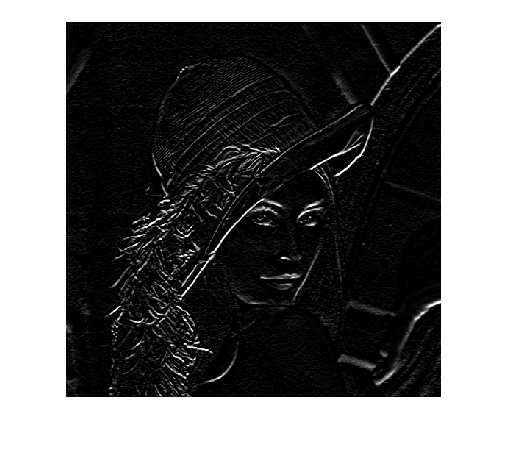

final1 = Convo2D(img,filter1,0,1);
imshow(final1)

(ii) Convolution with input containing multiple depth.

Logic: Call the Convo2D function N times for N depth and 3-d stack the output to get the final convolved result

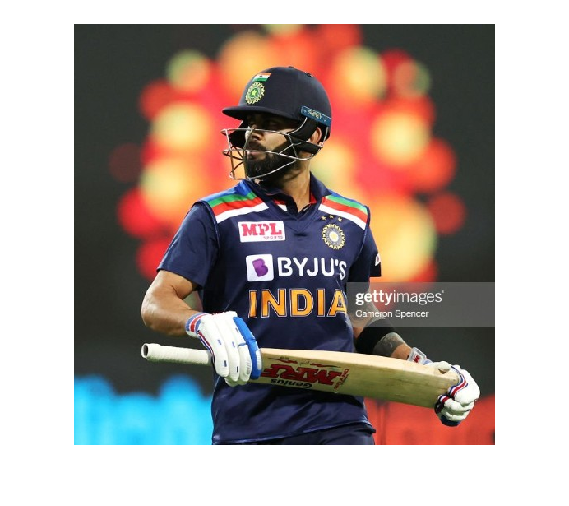

%Image with RGB components 3 depths
imgmult= imread("Virat.jpg");
imgmult=im2double(imgmult);
%Edge filter
filtera = [1,1,1;1,-9,1;1,1,1];
%3-D concatenate the filter
filter3d(:,:,1)=filtera;
filter3d(:,:,2)=filtera;
filter3d(:,:,3)=filtera;
imshow(imgmult)

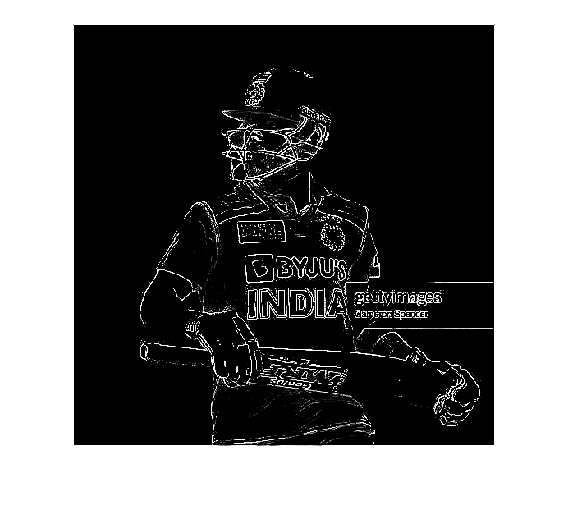

%Arguments of function are (Image,Filter,pad,Stride,Numberofdepths)
%We are giving 2 padded and stride 1 to get full convolution
final=Convo2d_multidepth(imgmult,filter3d,2,1,3);
imshow(final)

(iii)Convolution with input containing multiple depth such that the output size equal to the input size.

img_size= size(imgmult,1);
filter_size = size(filtera,1);
stride=1

stride =      1


%Padd to get equal size of input and output
pad = ((img_size(1)-1) * stride + filter_size - img_size(1))/2

pad =      1


final1=Convo2d_multidepth(imgmult,filter3d,pad,1,3);
size(imgmult)

ans =    512   512     3


size(final1)

ans =    512   512     3


 2. Design and apply a filter to smoothen the grayscale image.

I have taken a kernal of all ones (NxN)  and divded by N^2(to take avg) where  since, if we keep this kernal above a pixel , add all the 9 (N^2) pixels below this kernal, take average and replace the central pixel with new average value, It blurs/ smoothens the image.

It actually removes High Frequency content like edges and noise and this is the reason for blurrness

img1=imread("Virat.jpg");
%Convert to grayscale
img1=rgb2gray(img1);
img1=im2double(img1);
N=5

N =      5


%Smoothen Filter
kernal = ones(N,N)/N^2

kernal =    0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000


final_op=Convo2D(img1,kernal,2,1)

final_op =    0.070588235294118   0.094117647058824   0.117647058823529   0.117960784313725   0.118274509803922   0.118588235294118   0.118901960784314   0.119215686274510   0.119215686274510   0.119372549019608   0.119529411764706   0.119686274509804   0.120000000000000   0.120313725490196   0.120000000000000   0.119686274509804   0.119372549019608   0.118745098039216   0.118274509803922   0.118274509803922   0.118431372549020   0.118588235294118   0.118745098039216   0.118588235294118   0.118901960784314   0.119529411764706   0.119686274509804   0.119058823529412   0.118588235294118   0.118431372549020   0.117490196078431   0.117019607843137   0.117333333333333   0.117803921568627   0.117960784313725   0.118745098039216   0.119686274509804   0.120627450980392   0.120627450980392   0.120470588235294   0.120156862745098   0.119529411764706   0.118588235294118   0.118274509803922   0.117960784313725   0.117960784313725   0.118117647058824   0.118745098039216   0.119529411764706   0.1200

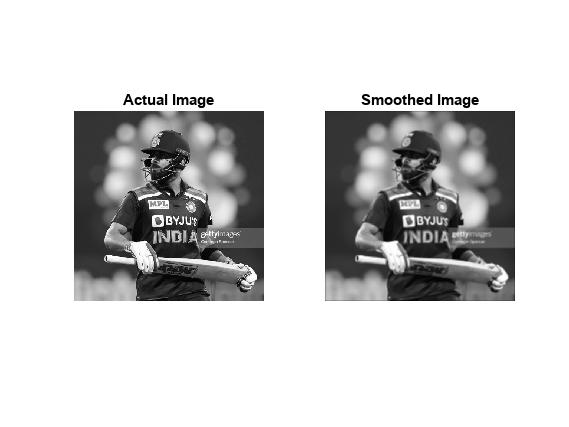

figure;
subplot(1,2,1)
imshow(img1)
title("Actual Image")
subplot(1,2,2)
imshow(final_op)
title("Smoothed Image")

Observe that The image blurs on the averaging operation filter

3. Analyze the effect of filter size 3 x 3 and 4 x 4 on smoothening the grayscale image.

%taking N=3x3
N=3

N =      3


kernal1 = ones(N,N)/N^2

kernal1 =    0.111111111111111   0.111111111111111   0.111111111111111
   0.111111111111111   0.111111111111111   0.111111111111111
   0.111111111111111   0.111111111111111   0.111111111111111


final_op1=Convo2D(img1,kernal,2,1)

final_op1 =    0.070588235294118   0.094117647058824   0.117647058823529   0.117960784313725   0.118274509803922   0.118588235294118   0.118901960784314   0.119215686274510   0.119215686274510   0.119372549019608   0.119529411764706   0.119686274509804   0.120000000000000   0.120313725490196   0.120000000000000   0.119686274509804   0.119372549019608   0.118745098039216   0.118274509803922   0.118274509803922   0.118431372549020   0.118588235294118   0.118745098039216   0.118588235294118   0.118901960784314   0.119529411764706   0.119686274509804   0.119058823529412   0.118588235294118   0.118431372549020   0.117490196078431   0.117019607843137   0.117333333333333   0.117803921568627   0.117960784313725   0.118745098039216   0.119686274509804   0.120627450980392   0.120627450980392   0.120470588235294   0.120156862745098   0.119529411764706   0.118588235294118   0.118274509803922   0.117960784313725   0.117960784313725   0.118117647058824   0.118745098039216   0.119529411764706   0.120

%taking N=4x4
N=4

N =      4


kernal2 = ones(N,N)/N^2

kernal2 =    0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000


final_op2=Convo2D(img1,kernal,2,1)

final_op2 =    0.070588235294118   0.094117647058824   0.117647058823529   0.117960784313725   0.118274509803922   0.118588235294118   0.118901960784314   0.119215686274510   0.119215686274510   0.119372549019608   0.119529411764706   0.119686274509804   0.120000000000000   0.120313725490196   0.120000000000000   0.119686274509804   0.119372549019608   0.118745098039216   0.118274509803922   0.118274509803922   0.118431372549020   0.118588235294118   0.118745098039216   0.118588235294118   0.118901960784314   0.119529411764706   0.119686274509804   0.119058823529412   0.118588235294118   0.118431372549020   0.117490196078431   0.117019607843137   0.117333333333333   0.117803921568627   0.117960784313725   0.118745098039216   0.119686274509804   0.120627450980392   0.120627450980392   0.120470588235294   0.120156862745098   0.119529411764706   0.118588235294118   0.118274509803922   0.117960784313725   0.117960784313725   0.118117647058824   0.118745098039216   0.119529411764706   0.120

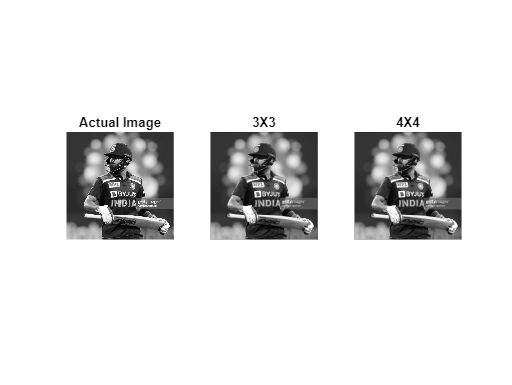

figure;
subplot(1,3,1)
imshow(img1)
title("Actual Image")
subplot(1,3,2)
imshow(final_op1)
title("3X3")
subplot(1,3,3)
imshow(final_op2)
title("4X4")

We blur our image with increasing sizes kernels. The larger our kernel becomes, the more blurred our image will appear.

Your image will become progressively more blurred as kernal dimension increases This could easily lead to a point where you lose the edges of important structural objects in the image.

function conv2 = Convo2d_multidepth(Image,Filter,padding,stride,depth_size)
%Output size of Matrix given by the formula
conv2_size = floor((size(Image,1)+ 2*padding - size(Filter,1))/ stride + 1) ;
conv2 = zeros(conv2_size,conv2_size,size(Image,depth_size));
%Calling the Convo2D function for each depth and then adding to get
%convolved output
    for i=1:size(Image,depth_size)
        conv2 = conv2+ Convo2D(Image(:,:,i),Filter(:,:,i),padding,stride);
    end
end



function conv = Convo2D(Image,Filter,padding,stride)

%Finding Size of Input Image
Img_size=size(Image,1);
%Zero-padding on both sides (Left and Right), based on given length
Image = [zeros(padding,Img_size);Image;zeros(padding,Img_size)];
%Zero-padding on both sides (Up and Down), based on given length
Image = [zeros(Img_size+2*padding,padding),Image,zeros(Img_size+2*padding,padding)];
%Size of Filter
Filter_size = size(Filter,1);


%Output size of Matrix given by the formula
conv_size = floor((Img_size- Filter_size + 2*padding)/ stride + 1) ;
conv = zeros(conv_size,conv_size); 
%For each row and column we are multplying Image and kernal where they
%overlap and then move the kernal based on stride
    for i = 1:conv_size
        for j = 1:conv_size
            r_start = (i-1)*stride+1 ;
            c_start = (j-1)*stride+1 ;
            conv(i,j) = sum(sum(Filter.*Image(r_start:r_start+Filter_size-1,c_start:c_start+Filter_size-1)));
        end
    end
end